format long eng;
kbr1b_x = importdata("KBR1B_2020-09-28_Y_04.txt");
gni1b_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni1b_b = importdata("GNI1B_2020-09-28_D_04.txt");
sca1b_a = importdata("SCA1B_2020-09-28_C_04.txt");
sca1b_b = importdata("SCA1B_2020-09-28_D_04.txt");
acc1b_a = importdata("ACT1B_2020-09-28_C_04.txt");
acc1b_b = importdata("ACT1B_2020-09-28_D_04.txt");

los = gni1b_b.data(:, 1: 3) - gni1b_a.data(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
rotm_a = zeros(17280, 3, 3);
rotm_b = zeros(17280, 3, 3);
eqa = zeros(17280, 6);
eqb = kbr1b_x(:, 2) - dis(1: 5: end);
for i = 1: 17280
    eqa(i, 1: 3) = los(i*5-4, :) * quat2rotm(sca1b_a.data(i*5-4, 2: 5));
    eqa(i, 4: 6) = los(i*5-4, :) * quat2rotm(sca1b_b.data(i*5-4, 2: 5));
end
diff_eqa = diff(eqa, 1);
% 10522: 11121
% 3695: 4284
% 3695: 4284
% 5972: 6571

diff2_eqa = diff(diff_eqa, 1);
diff3_eqa = diff(diff2_eqa, 1);
diff_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end));
diff2_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end), 2);
diff3_eqb = diff(diff2_eqb);
diff2_eqb = filter_pdfree(Num, diff2_eqb);
diff2_eqa = filter_pdfree(Num, diff2_eqa);
diff3_eqa = filter_pdfree(Num, diff3_eqa);
diff3_eqb = filter_pdfree(Num, diff3_eqb);
% fft_diff3_eqb = fft(diff3_eqb(10522: 11021));
% fft_diff3_eqa = [fft(diff3_eqa(10522: 11021, 4)), fft(diff3_eqa(10522: 11021, 5))];
% eqb = [fft_diff3_eqb(11); fft_diff3_eqb(21)];
% eqa = [fft_diff3_eqa(11, :); fft_diff3_eqa(21, :)];
% eqa_real = real(eqa);
% eqa_imag = imag(eqa);
% eqb_real = real(eqb);
% eqb_imag = imag(eqb);
% 
% eqa_abs = abs(eqa);
% eqa_ang = angle(eqa);
% eqb_abs = abs(eqb);
% eqb_ang = angle(eqb);

lsqr(diff3_eqa(5972: 6571, :), diff3_eqb(5972: 6571))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.061。


ans =     12.8557055992066e-006
    4.59801496652982e-003
    44.1713204369478e-003
    1.40358829026130e+000
    22.9439459831763e-003
   -1.49636808218691e-003


lsqr(diff2_eqa(5972: 6571, :), diff2_eqb(5972: 6571))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.077。


ans =     41.7522754445992e-006
    8.14879236254080e-003
    175.296988419100e-003
    1.40401868966644e+000
    13.0882151270358e-003
   -1.50021930518305e-003


lsqr(diff3_eqa(3695: 4284, :), diff3_eqb(3695: 4284))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.076。


ans =     21.7120343422019e-006
   -3.96061426008826e-003
    42.5665333650909e-003
    1.40780445810987e+000
    654.089153922487e-006
    3.83842010198348e-003


lsqr(diff2_eqa(3695: 4284, :), diff2_eqb(3695: 4284))

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.087。


ans =     37.2816427913503e-006
   -14.9090933125139e-003
    224.989820678295e-003
    1.40195329263776e+000
    100.940555011165e-003
    3.98800969982388e-003


solver_spectral(diff2_eqa(3695: 4284, :), diff2_eqb(3695: 4284), [4 6], 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。


ans =     382.732110866655e-009   -11.0590863798743e-006
    193.378145166304e-009    8.35113211693564e-009


lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。


ans =     584.607663779988e-009
    272.355060752230e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 2.4e-09。


ans =     1.40858429055182e+000
   -4.11401285600724e-003


solver_spectral(diff3_eqa(3695: 4284, :), diff3_eqb(3695: 4284), [4 6], 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。


ans =     48.0577137542249e-009   -1.38854415657769e-006
    48.4573716898026e-009    2.47798572106405e-009


lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。


ans =     73.3665617670187e-009
    68.2900356096843e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 6.9e-11。


ans =     1.40948797085021e+000
   -4.05445682247175e-003


solver_spectral(diff2_eqa(5972: 6571, :), diff2_eqb(5972: 6571), [4 6], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。


ans =     391.140969473019e-009   -11.0640303835322e-006
    193.714443467621e-009    8.07287973364625e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。


ans =     567.798435782402e-009
    271.759208739250e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.9e-09。


ans =     1.40295736130952e+000
   -1.72128363307023e-003


solver_spectral(diff3_eqa(10522: 11121, :), diff3_eqb(10522: 11121), [4 5], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。


ans =     48.0187233137600e-009   -1.39134433815566e-006
    48.7639937779397e-009    12.3840266741265e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。


ans =     71.9880151878696e-009
    72.1741507017666e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.8e-11。


ans =     1.48023645038149e+000
   -653.289494510205e-006


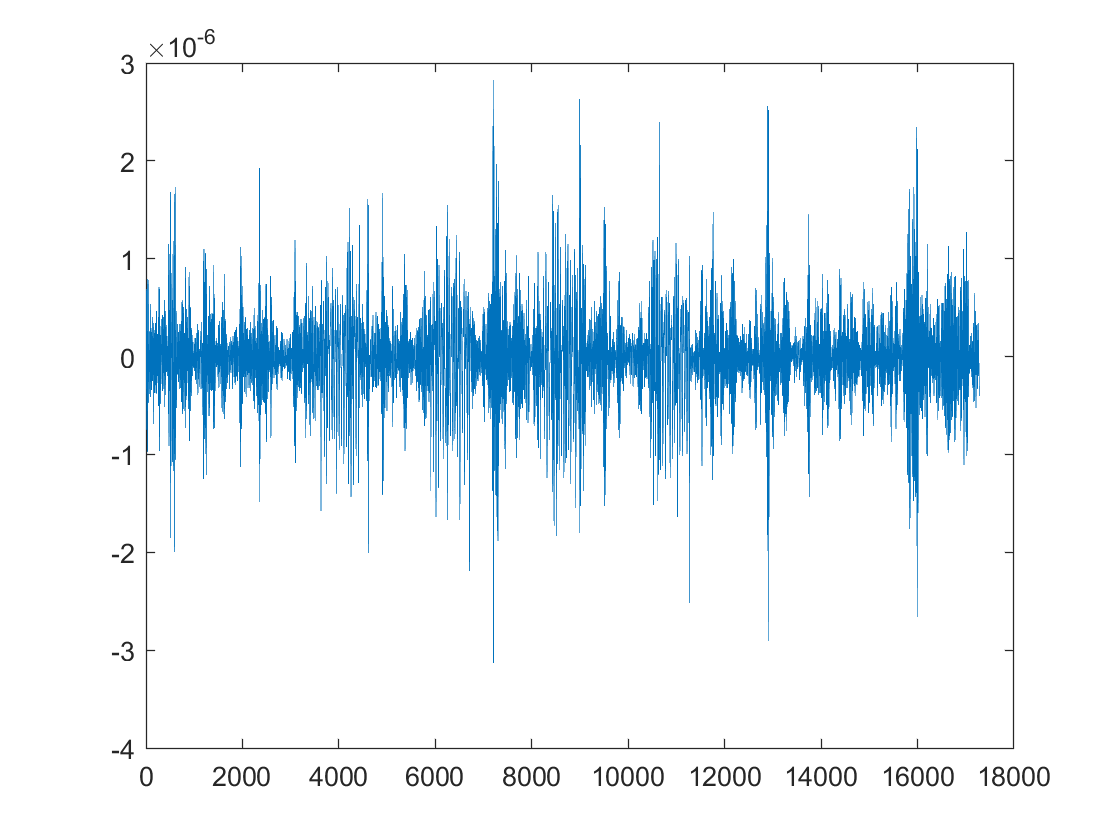

acc_grav = importdata("..//..//temp//acc_grav_calibra1.txt");
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-28_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-28_D_04.txt");
gni_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni_b = importdata("GNI1B_2020-09-28_D_04.txt");
kbr_x = importdata("KBR1B_2020-09-28_Y_04.txt");
range_acc = kbr_x(:, 4);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav;
figure; plot(range_acc_res)

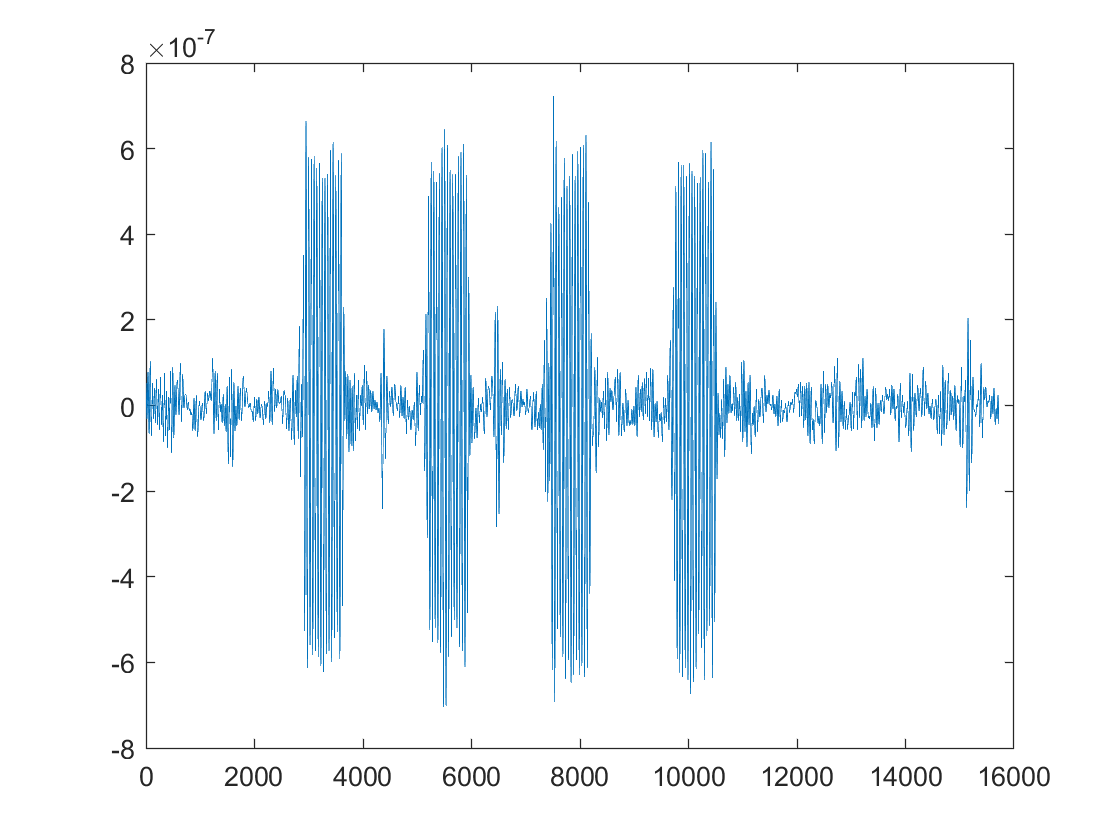

temp = filter_pdfree(Num1, range_acc_res);
figure; plot(temp)

spectral_component(filter_pdfree(Num, range_acc_res(10522: 11121)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.68。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.68。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.68。


ans =     583.716783820281e-009
    247.452267835872e-009


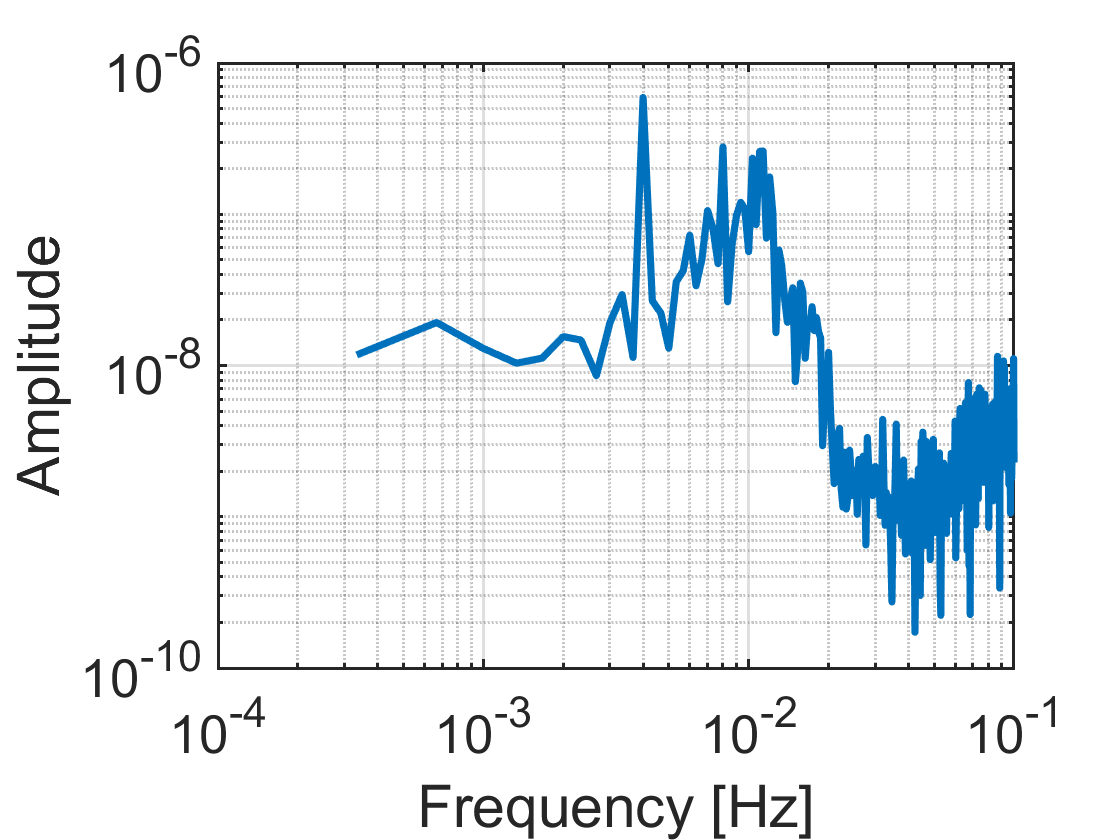

fft_plot(range_acc_res(10522: 11121), 0.2)

spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10522: 11121, 4)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.11。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.11。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.11。


ans =     382.971267156703e-009
    195.643586989006e-009


spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10522: 11121, 5)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


ans =     11.0942940349876e-006
    52.4754829460073e-009
